%{
%AER403 - Mechanism & Vibrations - W2021 - Final Project
%}

%%Reset Matlab Memory
close all
clear
clc

%Set Default RPM and Gear Ratio
rpm = 8000;
gear_ratio = 5402;

total_rotations = 12;
resolution_per_rotation = 100;

%Create Figure and all buttons/controls of the ui
mainfig = figure('Name','Simulation', 'NumberTitle','off'); 
sim_start = uicontrol('Parent',mainfig,'Style','pushbutton','String','Start','Units','normalized', 'Position',[0.01 0.07 .05 .05], 'callback', 'sim_state = 1;');
sim_pause = uicontrol('Parent',mainfig,'Style','pushbutton','String','Pause','Units','normalized', 'Position',[0.01 0.01 .05 .05], 'callback', 'sim_state = 0;');
draw_velocity = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Velocity','Units','normalized', 'Position',[0.01 0.13 .05 .05], 'callback', 'chng_velocity_draw = 1;');
draw_circle = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Intersection','Units','normalized', 'Position',[0.01 0.19 .05 .05], 'callback', 'chng_circle_draw = 1;');
draw_foot = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Path','Units','normalized', 'Position',[0.01 0.25 .05 .05], 'callback', 'chng_foot_draw = 1;');
rpm_set = uicontrol('Parent',mainfig,'Style','edit','String',rpm,'Units','normalized', 'Position',[0.01 0.31 .05 .03]);
uicontrol('Parent',mainfig,'Style','text','String','RPM:','Units','normalized', 'Position',[0.01 0.34 .05 .025]);
gear_ratio_set = uicontrol('Parent',mainfig,'Style','edit','String',gear_ratio,'Units','normalized', 'Position',[0.01 0.38 .05 .03]);
uicontrol('Parent',mainfig,'Style','text','String','Gear Ratio:','Units','normalized', 'Position',[0.01 0.42 .05 .025]);
draw_leg_2 = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Leg 2','Units','normalized', 'Position',[0.94 0.01 .05 .05], 'callback', 'chng_leg_2 = 1;');
draw_leg_3 = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Leg 3','Units','normalized', 'Position',[0.94 0.07 .05 .05], 'callback', 'chng_leg_3 = 1;');
draw_leg_4 = uicontrol('Parent',mainfig,'Style','pushbutton','String','Draw Leg 4','Units','normalized', 'Position',[0.94 0.13 .05 .05], 'callback', 'chng_leg_4 = 1;');

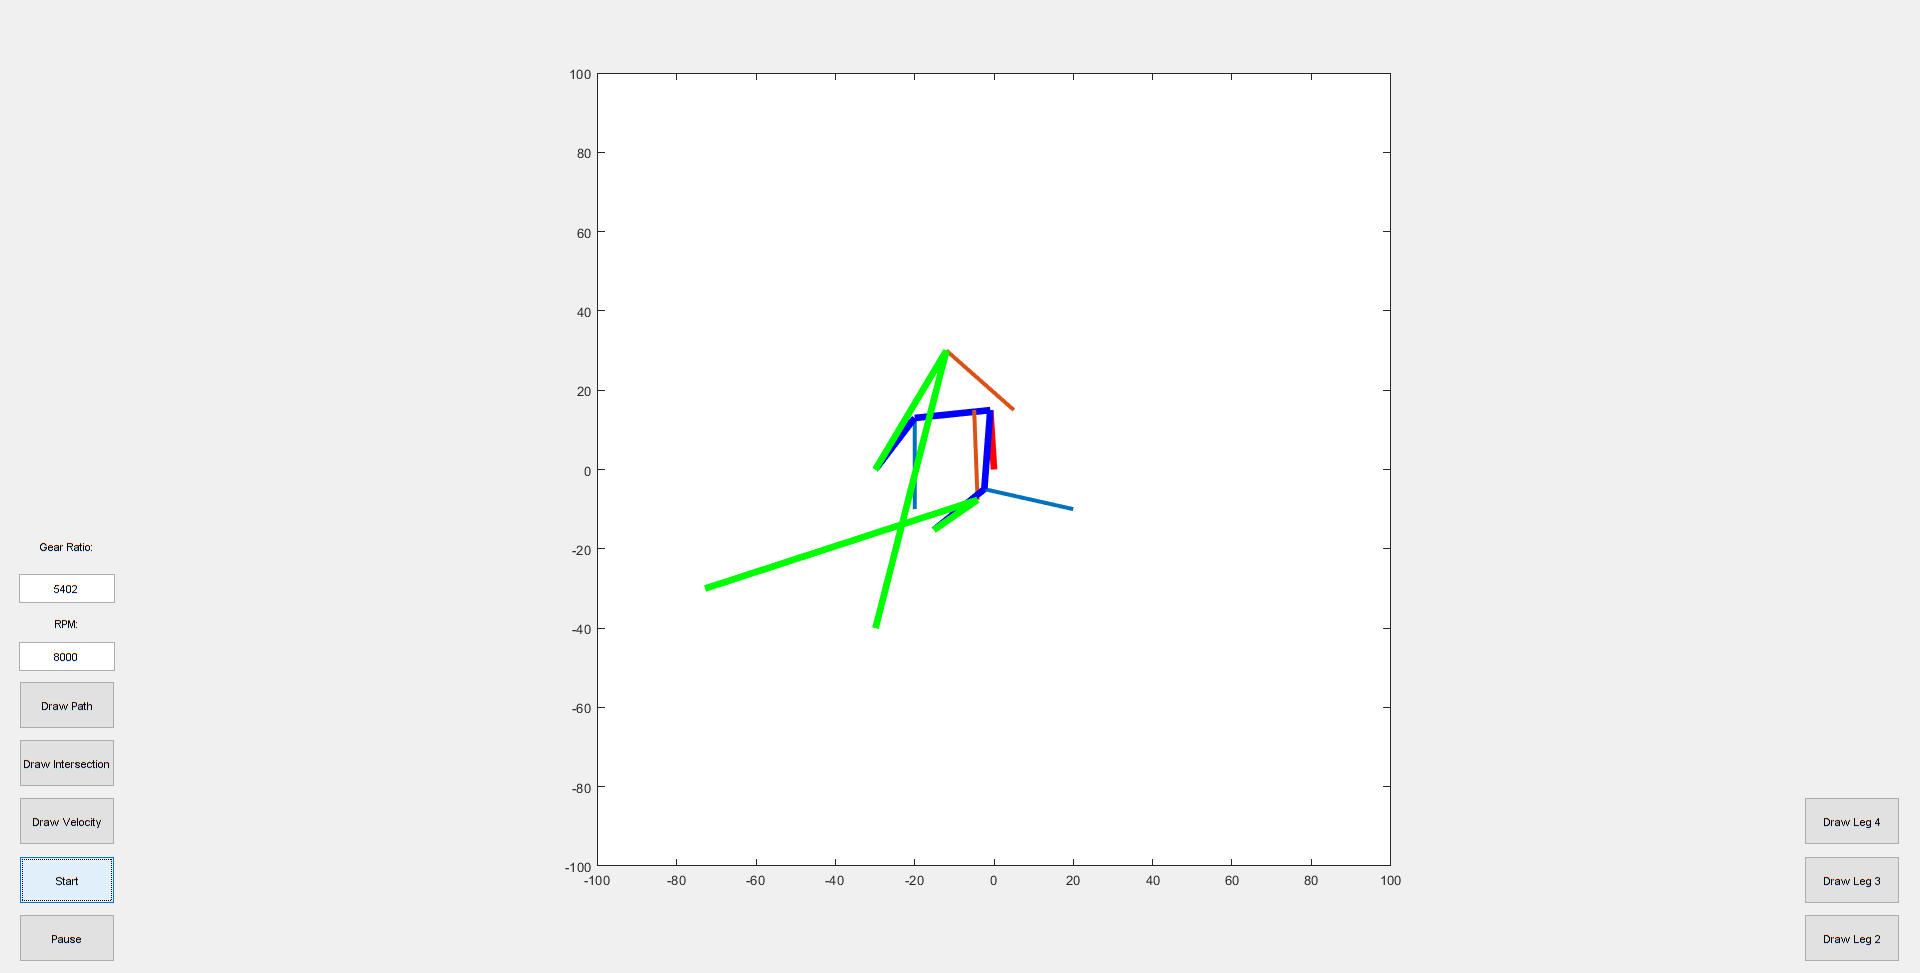

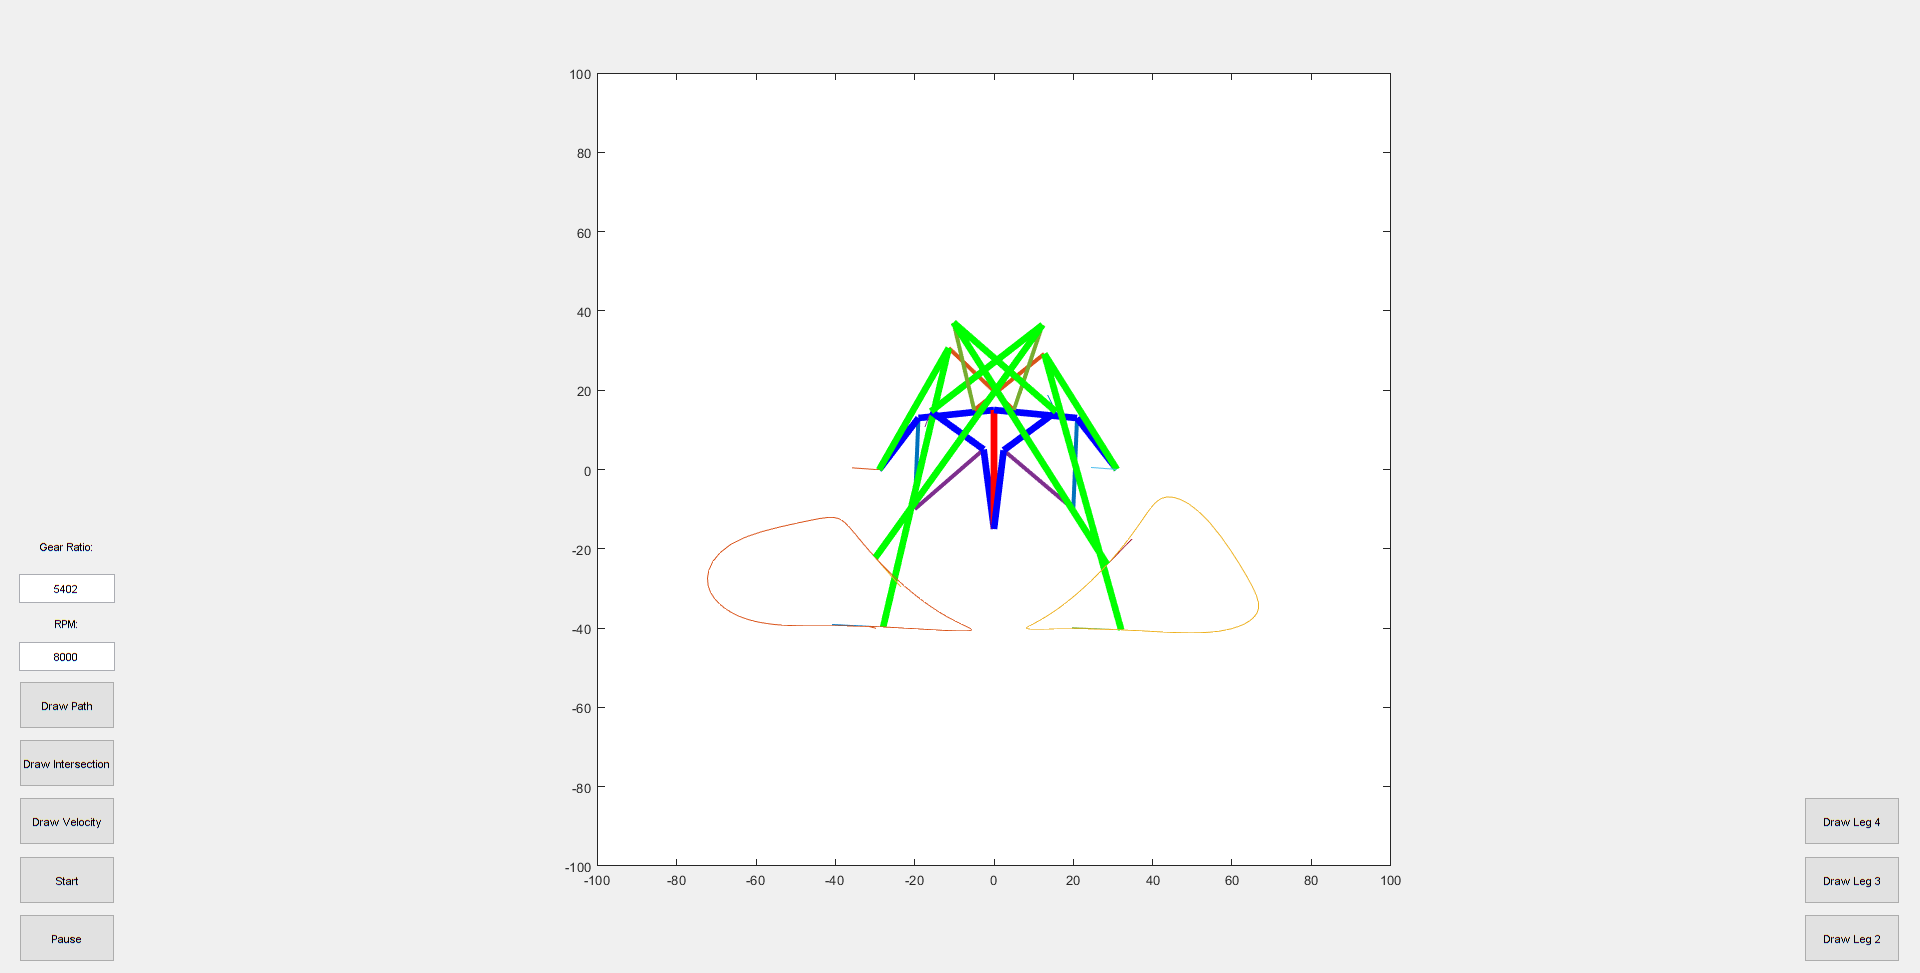



axis([-100 , 100, -100, 100]);
motor_rotation_point = [0, 0];
link_input_point = [0, 15];
joint_bottom_point = [-20, -10];
joint_bottom_connection_point = [-20, 13];
joint_top_point = [5, 15];
joint_top_connection_point = [-12, 30];
leg_mid_point = [-30, 0];
leg_bottom_point = [-30, -40];

%MAKE MAIN JOINT
pivot_bottom_radius = sqrt((joint_bottom_point(1) - joint_bottom_connection_point(1))^2+(joint_bottom_point(2) - joint_bottom_connection_point(2))^2);
pivot_top_radius = sqrt((joint_top_point(1) - joint_top_connection_point(1))^2 + (joint_top_point(2) - joint_top_connection_point(2))^2);

leg_motor_link_length = sqrt((joint_bottom_connection_point(1) - link_input_point(1))^2 + (joint_bottom_connection_point(2) - link_input_point(2))^2);
leg_motor_link_length_output = sqrt((joint_top_connection_point(1) - leg_mid_point(1))^2 + (joint_top_connection_point(2) - leg_mid_point(2))^2);

motor_arm = link([motor_rotation_point; link_input_point]);
leg_motor_link = link([link_input_point; joint_bottom_connection_point; leg_mid_point]);
leg_link = link([leg_mid_point; joint_top_connection_point; leg_bottom_point]);
pivot_arm_bottom = pivot_link(joint_bottom_point, pivot_bottom_radius);
pivot_arm_top = pivot_link(joint_top_point, pivot_top_radius);


motor_arm.set_input_joint(1,0);
motor_arm.set_input_function("rotation",0,[0,pi]);
motor_arm.set_output_joints(2,leg_motor_link);

leg_motor_link.set_input_joint(1, motor_arm);
leg_motor_link.set_pivot_links(2, pivot_arm_bottom);
leg_motor_link.set_output_joints(3, leg_link);

leg_link.set_input_joint(1, leg_motor_link);
leg_link.set_pivot_links(2, pivot_arm_top);
leg_link.set_output_joints(3, 0);

link_input_point_3 = link_input_point;
joint_bottom_point_3 = [20, -10];
joint_bottom_connection_point_3 = [20, 13];
joint_top_point_3 = [-5, 15];
joint_top_connection_point_3 = [12, 30];
leg_mid_point_3 = [30, 0];
leg_bottom_point_3 = [30, -40];

motor_arm_3 = link([motor_rotation_point; link_input_point]);
leg_motor_link_3 = link([link_input_point; joint_bottom_connection_point_3; leg_mid_point_3]);
leg_link_3 = link([leg_mid_point_3; joint_top_connection_point_3; leg_bottom_point_3]);
pivot_arm_bottom_3 = pivot_link(joint_bottom_point_3, pivot_bottom_radius);
pivot_arm_top_3 = pivot_link(joint_top_point_3, pivot_top_radius);


motor_arm_3.set_input_joint(1,0);
motor_arm_3.set_input_function("rotation",0,[0,pi]);
motor_arm_3.set_output_joints(2,leg_motor_link_3);

leg_motor_link_3.set_input_joint(1, motor_arm_3);
leg_motor_link_3.set_pivot_links(2, pivot_arm_bottom_3);
leg_motor_link_3.set_output_joints(3, leg_link_3);

leg_link_3.set_input_joint(1, leg_motor_link_3);
leg_link_3.set_pivot_links(2, pivot_arm_top_3);
leg_link_3.set_output_joints(3, 0);



sim_state = 0;
velocity_draw = 0;
circle_draw = 0;
foot_draw = 0;
leg_2_draw = 1;
leg_3_draw = 1;
leg_4_draw = 1;
chng_velocity_draw = 0;
chng_circle_draw = 0;
chng_foot_draw = 0;
chng_leg_2 = 0;
chng_leg_3 = 0;
chng_leg_4 = 0;

foot_pos = [];
foot_pos_2 = [];

for i = 1:total_rotations*resolution_per_rotation
    
    rpm = str2double(rpm_set.String);
    gear_ratio = str2double(gear_ratio_set.String);
    
    rps = rpm*gear_ratio/60;
    
    
    while sim_state == 0
        pause(0.1)
    end
    
    subplot(1,1,1)
    
    pivot_arm_bottom.update_point(leg_motor_link.joint_points(1,:), leg_motor_link_length, 0);
    pivot_arm_top.update_point(leg_motor_link.joint_points(3,:), leg_motor_link_length_output, 1);
    
    
    motor_arm.update_now(1,resolution_per_rotation, 0)
    leg_motor_link.update_now(1,resolution_per_rotation,0)
    leg_link.update_now(1,resolution_per_rotation,0)
    
    pivot_arm_bottom.draw_now();
    
    hold on
    axis([-100 , 100, -100, 100]);
    axis square;
    
    pivot_arm_top.draw_now();
    
    motor_arm.draw_now('red')
    leg_motor_link.draw_now('blue')
    leg_link.draw_now('green')
    
    pivot_arm_bottom_3.update_point(leg_motor_link_3.joint_points(1,:), leg_motor_link_length, 0);
    pivot_arm_top_3.update_point(leg_motor_link_3.joint_points(3,:), leg_motor_link_length_output, 1);
    
    motor_arm_3.update_now(1,resolution_per_rotation, 0)
    leg_motor_link_3.update_now(1,resolution_per_rotation,0)
    leg_link_3.update_now(1,resolution_per_rotation,0)
    
    if leg_3_draw
        pivot_arm_bottom_3.draw_now();
        pivot_arm_top_3.draw_now();
        motor_arm_3.draw_now('red')
        leg_motor_link_3.draw_now('blue')
        leg_link_3.draw_now('green')
    end
    
    if chng_velocity_draw
        chng_velocity_draw = 0;
        velocity_draw = ~velocity_draw;
    end
    
    if chng_circle_draw
        chng_circle_draw = 0;
        circle_draw = ~circle_draw;
    end
    
    if chng_foot_draw
        chng_foot_draw = 0;
        foot_draw = ~foot_draw;
    end
    
    if chng_leg_2
        chng_leg_2 = 0;
        leg_2_draw = ~leg_2_draw;
    end
    
    if chng_leg_3
        chng_leg_3 = 0;
        leg_3_draw = ~leg_3_draw;
    end
    
    if chng_leg_4
        chng_leg_4 = 0;
        leg_4_draw = ~leg_4_draw;
    end
    
    
    if velocity_draw
        leg_link.draw_velocity(resolution_per_rotation/rps*1000);
        leg_motor_link.draw_velocity(resolution_per_rotation/rps*1000);
        if leg_2_draw && i > resolution_per_rotation/2
            leg_link_2.draw_velocity(resolution_per_rotation/rps*1000);
            leg_motor_link_2.draw_velocity(resolution_per_rotation/rps*1000);
        end
        if leg_3_draw
            leg_link_3.draw_velocity(resolution_per_rotation/rps*1000);
            leg_motor_link_3.draw_velocity(resolution_per_rotation/rps*1000);
        end
        if leg_4_draw && i > resolution_per_rotation/2
            leg_link_4.draw_velocity(resolution_per_rotation/rps*1000);
            leg_motor_link_4.draw_velocity(resolution_per_rotation/rps*1000);
        end
    end
    
    if circle_draw
        pivot_arm_top.draw_circles(leg_motor_link.joint_points(3,:),leg_motor_link_length_output);
        pivot_arm_bottom.draw_circles(leg_motor_link.joint_points(1,:), leg_motor_link_length);
    end
    
    if foot_draw
        plot(foot_pos(:,1),foot_pos(:,2));
        if (leg_3_draw || leg_4_draw) && i > 25
            plot(foot_pos_2(:,1),foot_pos_2(:,2));
        end
    end    
    
    foot_pos = [foot_pos ; leg_link.joint_points(3,:)];
    if i > 24
        foot_pos_2 = [foot_pos_2 ; leg_link_3.joint_points(3,:)];
    end
       
    if i == resolution_per_rotation/2
%         link_input_point_2 = -link_input_point;
%         joint_bottom_connection_point_2 = leg_motor_link.joint_points(2,:);
%         joint_top_connection_point_2 = leg_link.joint_points(2,:);
%         leg_mid_point_2 = leg_link.joint_points(1,:);
%         leg_bottom_point_2 = leg_link.joint_points(3,:);
        
        link_input_point_2 = link_input_point;
        joint_bottom_connection_point_2 = joint_bottom_connection_point;
        joint_top_connection_point_2 = joint_top_connection_point;
        leg_mid_point_2 = leg_mid_point;
        leg_bottom_point_2 = leg_bottom_point;
        
        
        motor_arm_2 = link([motor_rotation_point; link_input_point_2]);
        leg_motor_link_2 = link([link_input_point_2; joint_bottom_connection_point_2; leg_mid_point_2]);
        leg_link_2 = link([leg_mid_point_2; joint_top_connection_point_2; leg_bottom_point_2]);
        pivot_arm_bottom_2 = pivot_link(joint_bottom_point, pivot_bottom_radius);
        pivot_arm_top_2 = pivot_link(joint_top_point, pivot_top_radius);
        
        
        motor_arm_2.set_input_joint(1,0);
        motor_arm_2.set_input_function("rotation",0,[0,pi]);
        motor_arm_2.set_output_joints(2,leg_motor_link_2);
        
        leg_motor_link_2.set_input_joint(1, motor_arm_2);
        leg_motor_link_2.set_pivot_links(2, pivot_arm_bottom_2);
        leg_motor_link_2.set_output_joints(3, leg_link_2);
        
        leg_link_2.set_input_joint(1, leg_motor_link_2);
        leg_link_2.set_pivot_links(2, pivot_arm_top_2);
        leg_link_2.set_output_joints(3, 0);
        
        %%
        
        link_input_point_4 = link_input_point;
        joint_bottom_point_4 = [20, -10];
        joint_bottom_connection_point_4 = [20, 13];
        joint_top_point_4 = [-5, 15];
        joint_top_connection_point_4 = [12, 30];
        leg_mid_point_4 = [30, 0];
        leg_bottom_point_4 = [30, -40];
        
        
        motor_arm_4 = link([motor_rotation_point; link_input_point]);
        leg_motor_link_4 = link([link_input_point; joint_bottom_connection_point_4; leg_mid_point_4]);
        leg_link_4 = link([leg_mid_point_4; joint_top_connection_point_4; leg_bottom_point_4]);
        pivot_arm_bottom_4 = pivot_link(joint_bottom_point_3, pivot_bottom_radius);
        pivot_arm_top_4 = pivot_link(joint_top_point_3, pivot_top_radius);
        
        
        motor_arm_4.set_input_joint(1,0);
        motor_arm_4.set_input_function("rotation",0,[0,pi]);
        motor_arm_4.set_output_joints(2,leg_motor_link_4);
        
        leg_motor_link_4.set_input_joint(1, motor_arm_4);
        leg_motor_link_4.set_pivot_links(2, pivot_arm_bottom_4);
        leg_motor_link_4.set_output_joints(3, leg_link_4);
        
        leg_link_4.set_input_joint(1, leg_motor_link_4);
        leg_link_4.set_pivot_links(2, pivot_arm_top_4);
        leg_link_4.set_output_joints(3, 0);
        
    end
    
    if i > resolution_per_rotation/2 
        pivot_arm_bottom_2.update_point(leg_motor_link_2.joint_points(1,:), leg_motor_link_length, 0);
        pivot_arm_top_2.update_point(leg_motor_link_2.joint_points(3,:), leg_motor_link_length_output, 1);
    
        motor_arm_2.update_now(1,resolution_per_rotation, 0)
        leg_motor_link_2.update_now(1,resolution_per_rotation,0)
        leg_link_2.update_now(1,resolution_per_rotation,0)
        
        
        
        
        pivot_arm_bottom_4.update_point(leg_motor_link_4.joint_points(1,:), leg_motor_link_length, 0);
        pivot_arm_top_4.update_point(leg_motor_link_4.joint_points(3,:), leg_motor_link_length_output, 1);
    
        motor_arm_4.update_now(1,resolution_per_rotation, 0)
        leg_motor_link_4.update_now(1,resolution_per_rotation,0)
        leg_link_4.update_now(1,resolution_per_rotation,0)
        
        if leg_2_draw
            pivot_arm_bottom_2.draw_now();
            
            pivot_arm_top_2.draw_now();
        
            motor_arm_2.draw_now('red')
            leg_motor_link_2.draw_now('blue')
            leg_link_2.draw_now('green')
        end
        
        if leg_4_draw
            pivot_arm_bottom_4.draw_now();
            
            pivot_arm_top_4.draw_now();
        
            motor_arm_4.draw_now('red')
            leg_motor_link_4.draw_now('blue')
            leg_link_4.draw_now('green')
        end
    end
    
    hold off
    
    pause(.05)
    
end